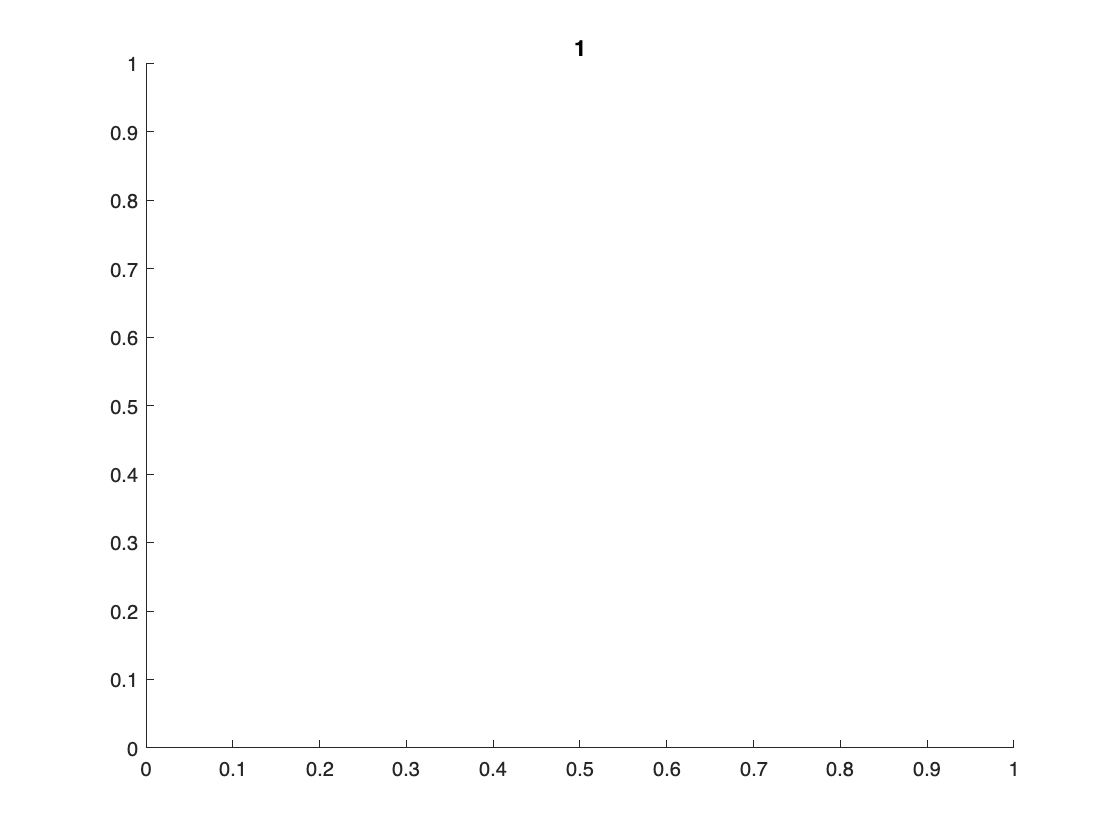

Unrecognized function or variable 'ld'.

Error in k_singledaymeanplotter (line 15)
        fill([ld ld ld*2 ld*2], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9]);

for j = 1:length(dark(3).h)
    figure(j); clf; title(num2str(j)); hold on;
    k_singledaymeanplotter(dark(3).h(j).day)
end


%     for kk = 1:length(ten2idx)
%         tench2(kk).day = KatieRegobwDayDessemblerhour(hkg(ten2idx(kk)), 2, ReFs, 3,kk);
%     end

    ten = [tench1 tench2];
    
    

[ exp, fish, ld] = k_fftdaymovabovemeans(ten);
%plot
figure(317); clf; title('FFT Dark to Light'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

    
      
        %ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * ld);
        plot((exp.hourtim .* crosshour)-pi, exp.meanofexperimentmeans, 'LineWidth', 2)
       
  
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
   

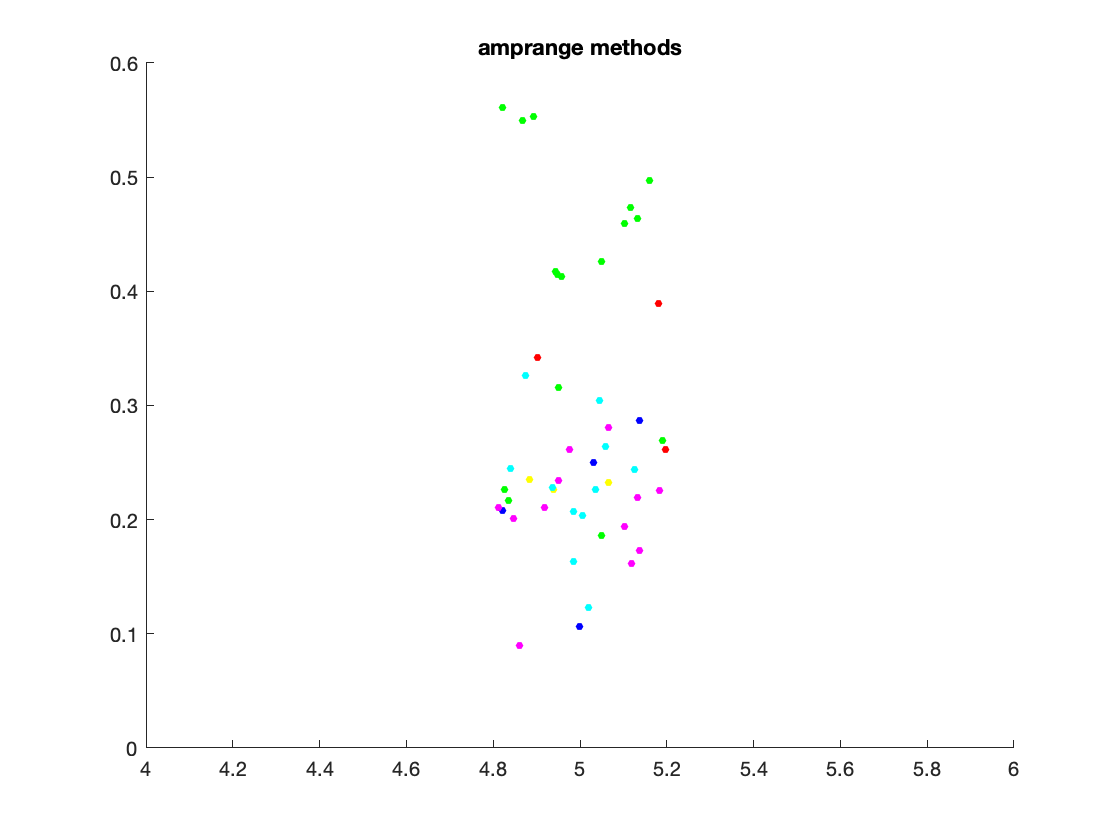


figure(98); clf; title('amprange methods'); hold on;

  

      
       
        for kk = 1:length(fish)
            clrbyfish = hsv(length(fish));
            for jj = 1:length(fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld, fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end

        plot(ld, expavgrange, 'k.', 'MarkerSize', 35);

Unrecognized function or variable 'expavgrange'.


    
    set(gca,'xscale', 'log', 'yscale', 'log');

% ReFs = 20;
% ld = 48;
% %48:48 LD
% idx = [3 4 5 44 80 81 82 106];%[3 4 5 44 80 81 82 106]
%                     %45 shit data - noise issues maybe
%                     %46 left out for now - bit messy not too bad
%                     %83 single day - kinda messy but not too bad
%                     %102 single day (starts with light)
%                     %107 messyeight
%     
%     for k = 1:length(foureightidx)
%         k
%         foureightdark(k).day = KatieRegobwDayDessemblerhour(kg(foureightidx(k)), 1, ReFs, 3, k);
%        % foureightlight(k).day = KatieRegobwDayDessemblerhour(kg(foureightidx(k)), 1, ReFs, 4);
%     end
% 
%     [hourtim, meanofexperimentmeans, hourampmax, ~] = k_fftdaymovabovemeans(foureightdark);
% 
% 
% %plot
% figure(317); clf; title('FFT Dark to Light'); hold on; 
%     set(gca,'XTick',-2*pi:pi:2*pi)
%     ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
% 
%     
%       
%         %ld(j,:) = dark(j).ld;
%         crosshour = (2*pi) / (2 * ld);
%         plot((hourtim .* crosshour)-pi, meanofexperimentmeans, 'LineWidth', 2)
%        
%   
%     plot([0,0], ylim, 'k-', 'LineWidth', 2);
%    
